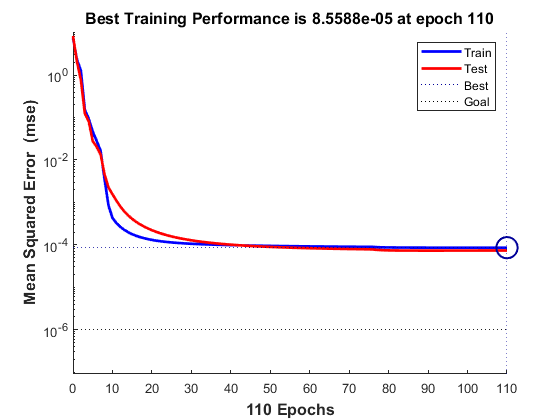


clear
echo on
load datafun4

[x,y]=simplefit_dataset;
n=length(y);
n2=fix(n/2);

net=fitnet(6);


net.divideFcn='divideind';      % indexove
net.divideParam.trainInd=indx_train;

net.divideParam.testInd=indx_test;


% Nastavenie parametrov trénovania
net.trainParam.goal = 1e-6;     % Ukon?ovacia podmienka na chybu SSE.
net.trainParam.show = 5;        % Frekvencia zobrazovania priebehu chyby trénovania net.trainParam.epochs = 100;  % Max. po?et trénovacích cyklov.
net.trainParam.epochs = 500;  	    % Max. pocet trénovacích cyklov.

% Trénovanie NS
[net,tr]=train(net,x,y);

% zobrazenie chyby siete pocas trenovania
plotperform(tr)

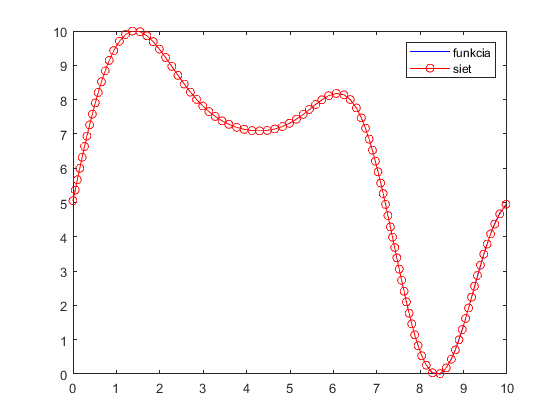


% Simulácia výstupu NS
outnetsim = sim(net,x);

% Vykreslenie priebehov
figure
plot(x,y,'b',x,outnetsim,'-or')
legend('funkcia','siet')

echo off